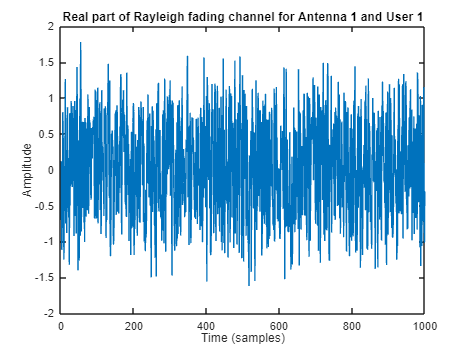

M = 128;        % Number of antennas at HMIMO base station
K = 5;          % Number of users
min_radius = 20;   % Minimum distance of users from HMIMO base station
radius = 100;      % Max distance of users from HMIMO base station
nSamples = 1000;    % Number of time samples to simulate time-varying channels
SNR_dB = 10;       % Signal-to-noise ratio in dB
SNR = 10^(SNR_dB/10); % Linear scale SNR
fD = 100;           % Maximum Doppler frequency (Hz) for Rician fading (user mobility)
Ts = 1e-3;         % Sampling interval in seconds
K_factor = 6;      % Rician K-factor in dB

% Convert K-factor from dB to linear scale
K_linear = 10^(K_factor/10);

hmimo_x = 0;
hmimo_y = 0;

% Randomly generate user positions with constraints (min and max distances)
user_angles = 2 * pi * rand(K, 1);
user_distances = min_radius + (radius - min_radius) * rand(K, 1);
user_x = user_distances .* cos(user_angles);
user_y = user_distances .* sin(user_angles);

% Pre-allocate memory for the Rician fading channel and beamforming gain
H = zeros(M, K, nSamples);
beamforming_gain = zeros(K, nSamples);

% Rician fading with Doppler
for timeIdx = 1:nSamples
    for userIdx = 1:K
        % LOS component
        theta_LOS = rand(1) * 2 * pi;
        h_LOS = sqrt(K_linear / (K_linear + 1)) * exp(1i * theta_LOS);
        
        % NLOS components
        h_real = sqrt(0.5 / (K_linear + 1)) * randn(M, 1);
        h_imag = sqrt(0.5 / (K_linear + 1)) * randn(M, 1);
        
        % Combine to form complex Gaussian channel coefficients (Rician fading)
        H(:, userIdx, timeIdx) = h_LOS + (h_real + 1i * h_imag);
    end
end

% Plot real part of Rayleigh fading for one antenna-user pair
figure;
plot(squeeze(real(H(1,1,:))));
title('Real part of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Amplitude');

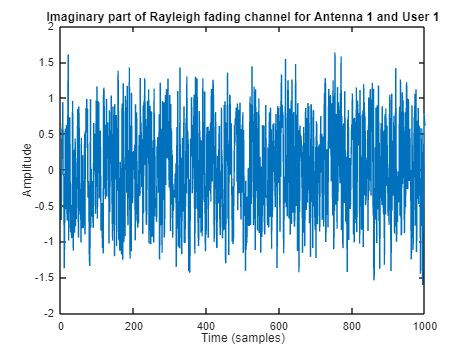


% Plot imaginary part of Rayleigh fading for one antenna-user pair
figure;
plot(squeeze(imag(H(1,1,:))));
title('Imaginary part of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Amplitude');

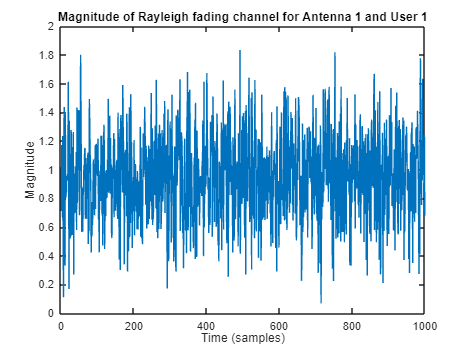


% Plot magnitude of Rayleigh fading for one antenna-user pair
figure;
plot(squeeze(abs(H(1,1,:))));
title('Magnitude of Rayleigh fading channel for Antenna 1 and User 1');
xlabel('Time (samples)');
ylabel('Magnitude');

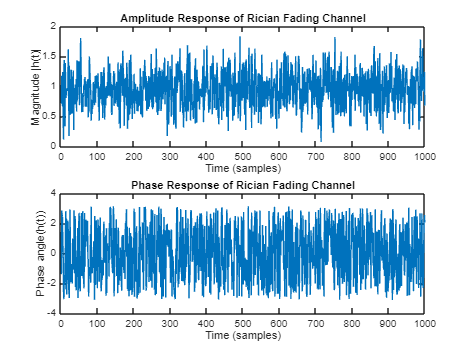


amplitude_response = abs(squeeze(H(1, 1, :)));
phase_response = angle(squeeze(H(1, 1, :)));

figure;
subplot(2, 1, 1);
plot(amplitude_response);
title('Amplitude Response of Rician Fading Channel');
xlabel('Time (samples)');
ylabel('Magnitude |h(t)|');

subplot(2, 1, 2);
plot(phase_response);
title('Phase Response of Rician Fading Channel');
xlabel('Time (samples)');
ylabel('Phase angle(h(t))');

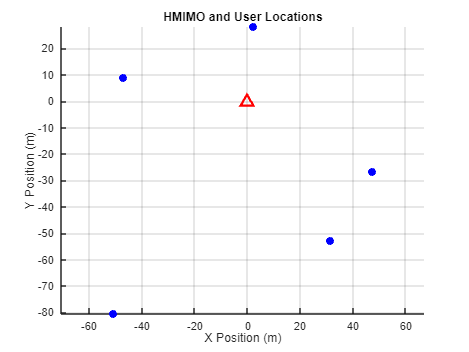


figure;
hold on;
plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2);
scatter(user_x, user_y, 50, 'b', 'filled');
title('HMIMO and User Locations');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

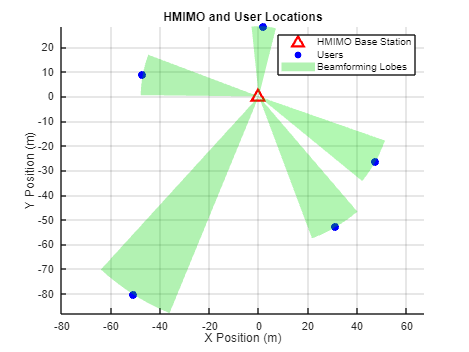



% Beamwidth for visualization (in degrees)
beamwidth_deg = 20;
beamwidth_rad = deg2rad(beamwidth_deg);

% Loop over time samples to simulate time-varying Rician channel and beamforming
for timeIdx = 1:nSamples
    cla;
    plot(hmimo_x, hmimo_y, 'r^', 'MarkerSize', 10, 'LineWidth', 2);
    scatter(user_x, user_y, 50, 'b', 'filled');

    % For each user, compute beamforming and visualize the beam lobe
    for userIdx = 1:K
        h_k = H(:, userIdx, timeIdx);
        w_k = h_k / norm(h_k);
        beamforming_gain(userIdx, timeIdx) = abs(h_k' * w_k)^2;

        % Calculate the angle between HMIMO and user
        dx = user_x(userIdx) - hmimo_x;
        dy = user_y(userIdx) - hmimo_y;
        angle_to_user = atan2(dy, dx);

        % Define the sector (beam lobe) parameters
        theta_start = angle_to_user - beamwidth_rad / 2;
        theta_end = angle_to_user + beamwidth_rad / 2;
        r_max = sqrt(dx^2 + dy^2);

        % Create the beam lobe as a sector
        theta = linspace(theta_start, theta_end, 100);
        r = linspace(0, r_max, 50);
        [Theta, R] = meshgrid(theta, r);
        [X, Y] = pol2cart(Theta, R);

        % Shift the beam lobe to HMIMO position
        X = X + hmimo_x;
        Y = Y + hmimo_y;

        % Beam lobe color intensity proportional to beamforming gain
        beam_intensity = beamforming_gain(userIdx, timeIdx);
        beam_color = [0, 1, 0] * min(1, beam_intensity / max(beamforming_gain(:)));

        % Plot the beam lobe
        surf(X, Y, zeros(size(X)), 'FaceColor', beam_color, 'EdgeColor', 'none', 'FaceAlpha', 0.3);
    end

    % Update legend
    legend('HMIMO Base Station', 'Users', 'Beamforming Lobes');
    view(2);
    drawnow;
    pause(0.05);
end